# Image Reconstruction — All Regularization Methods

This script implements and compares four regularization methods for image deblurring:

1. Tikhonov Regularization 2. Truncated SVD (TSVD) 3. Non-Stationary Iterated Tikhonov (NSIT) + Morozov Stopping 4. Fast NSIT (FNSIT) — Double-Correction Update

**Inverse Problem:**


$$y = A\,x + \varepsilon, \quad \varepsilon \sim \mathcal{N}(0,\sigma^2 I)$$


where $A$ is a Gaussian blur operator and $\varepsilon$ is additive noise.

**Error Metrics:**


$$\text{MSE} = \frac{1}{N}\sum_{i=1}^{N}(x_i^{\text{rec}}-x_i^{\text{true}})^2$$



$$\text{Relative Error} = \frac{\|x^{\text{rec}}-x^{\text{true}}\|}{\|x^{\text{true}}\|}$$


## 1. Load and Prepare Image

img = imread('296059.jpg');
if ndims(img) == 3
    img = rgb2gray(img);
end
x_true = double(img);
x_true = x_true / max(x_true(:));

[rows, cols] = size(x_true);
fprintf('Image size: %d x %d\n', rows, cols);

Image size: 321 x 481


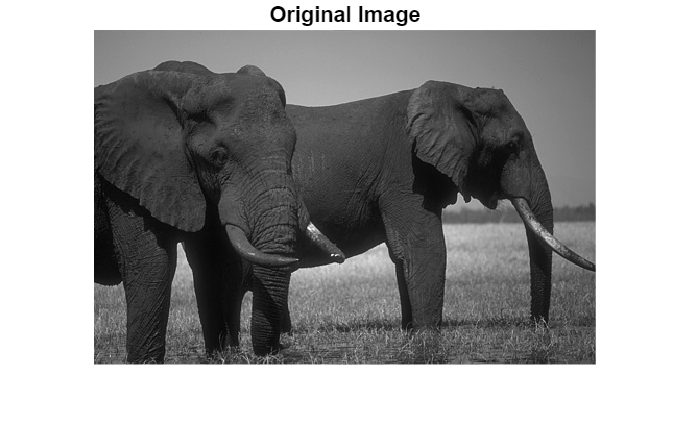


figure;
imshow(x_true, []);
title('Original Image');

## 2. Forward Operator

**Gaussian Point Spread Function (PSF):**


$$h(i,j) = \frac{1}{Z}\exp\!\left(-\frac{i^2+j^2}{2\sigma_k^2}\right), \quad Z=\sum_{i,j}h(i,j)$$


**Forward model:**


$$y = h * x + \varepsilon$$


**Adjoint operator** $A^T$: convolution with flipped kernel $h(-i,-j)$.

kernel_size = 9;
sigma_k = 2.0;

half = floor(kernel_size / 2);
[xx, yy] = meshgrid(-half:half, -half:half);
kernel = exp(-(xx.^2 + yy.^2) / (2 * sigma_k^2));
kernel = kernel / sum(kernel(:));

A_op  = @(x) imfilter(x, kernel, 'symmetric', 'same');
AT_op = @(x) imfilter(x, rot90(kernel, 2), 'symmetric', 'same');

## 3. Generate Noisy Observation

noise_std = 0.01;
rng(42);

Ax  = A_op(x_true);
eps = noise_std * randn(rows, cols);
y   = Ax + eps;

delta = norm(eps(:));
fprintf('Noise level delta = %.6f\n', delta);

Noise level delta = 3.933109


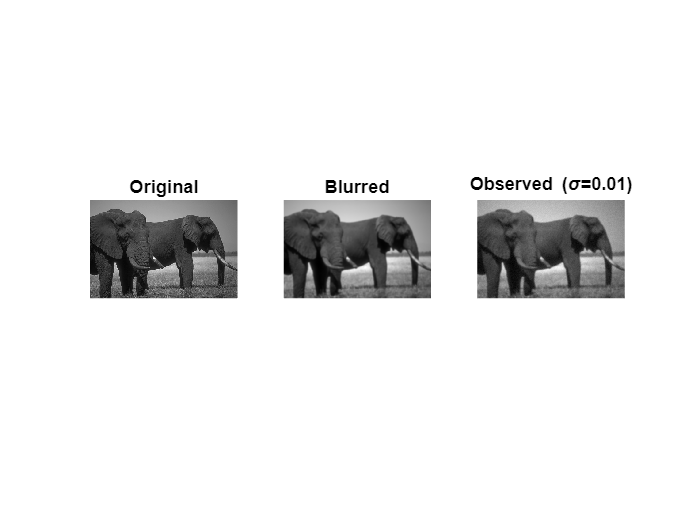


figure;
subplot(1,3,1); imshow(x_true, []); title('Original');
subplot(1,3,2); imshow(Ax, []);     title('Blurred');
subplot(1,3,3); imshow(y, []);      title(sprintf('Observed (\\sigma=%.2f)', noise_std));

## =========================================================

## METHOD 1: Tikhonov Regularization

## =========================================================

**Tikhonov solves the penalised least-squares problem:**


$$x_\lambda = \arg\min_x \left\{\|Ax-y\|^2 + \lambda\|x\|^2\right\}$$


**Closed-form:**


$$x_\lambda = (A^T A + \lambda I)^{-1} A^T y$$


**Gradient descent update:**


$$x^{(k+1)} = x^{(k)} - \tau\left[A^T(Ax^{(k)}-y) + \lambda x^{(k)}\right]$$


fprintf('\n--- Tikhonov Regularization ---\n');


--- Tikhonov Regularization ---


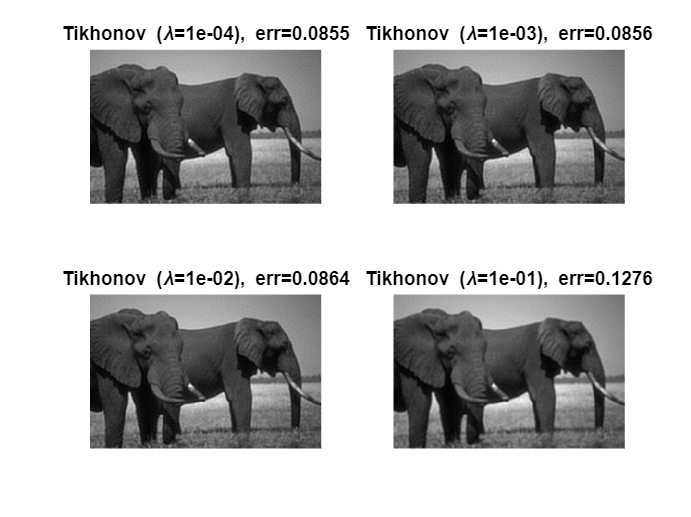


lambdas = [1e-4, 1e-3, 1e-2, 1e-1];
tikh_results = zeros(length(lambdas), 3); % [lambda, rel_err, mse]

figure;
for i = 1:length(lambdas)
    lam = lambdas(i);
    x_tikh = tikhonov_solve(A_op, AT_op, y, lam, 200, 0.1);
    rel_err = norm(x_tikh(:) - x_true(:)) / norm(x_true(:));
    mse_val = mean((x_tikh(:) - x_true(:)).^2);
    tikh_results(i,:) = [lam, rel_err, mse_val];
    
    subplot(2,2,i);
    imshow(x_tikh, []);
    title(sprintf('Tikhonov (\\lambda=%.0e), err=%.4f', lam, rel_err));
end


[~, best_idx] = min(tikh_results(:,3));
best_lam = tikh_results(best_idx, 1);
x_tikh_best = tikhonov_solve(A_op, AT_op, y, best_lam, 200, 0.1);
mse_tikh = tikh_results(best_idx, 3);
rel_tikh = tikh_results(best_idx, 2);

fprintf('Best lambda = %.0e\n', best_lam);

Best lambda = 1e-04


fprintf('Relative Error = %.6f\n', rel_tikh);

Relative Error = 0.085545


fprintf('MSE = %.8f\n', mse_tikh);

MSE = 0.00131522


## =========================================================

## METHOD 2: Truncated SVD (TSVD)

## =========================================================

**SVD of the forward operator:**


$$A = U \Sigma V^T = \sum_{i=1}^{r}\sigma_i u_i v_i^T$$


**TSVD reconstruction (truncate at index** $k$**):**


$$x_k = \sum_{i=1}^{k}\frac{u_i^T y}{\sigma_i} v_i$$


Small $\sigma_i$ amplify noise; truncation removes these components.

fprintf('\n--- Truncated SVD ---\n');


--- Truncated SVD ---


fprintf('Building explicit convolution matrix (this may take time)...\n');

Building explicit convolution matrix (this may take time)...



N = rows * cols;
A_mat = build_convolution_matrix(kernel, rows, cols);

Error using zeros
Requested 154401x154401 (177.6GB) array exceeds maximum array size preference (15.6GB). This might cause MATLAB to become unresponsive.

Error in sample_reg_methods_all>build_convolution_matrix (line 210)
A = zeros(N, N);

Related documentation


[U_svd, S_svd, V_svd] = svd(A_mat, 'econ');
s_vals = diag(S_svd);

y_vec = y(:);
x_vec_true = x_true(:);

ks = [5 15 30 60];
figure;
for i = 1:length(ks)
    k = ks(i);
    x_tsvd_vec = V_svd(:,1:k) * (U_svd(:,1:k)' * y_vec ./ s_vals(1:k));
    subplot(2,2,i);
    imshow(reshape(x_tsvd_vec, rows, cols), []);
    title(sprintf('TSVD (k=%d)', k));
end

% Find optimal k
best_mse_tsvd = inf;
best_k = 1;
for k = 1:min(length(s_vals), 100)
    x_k = V_svd(:,1:k) * (U_svd(:,1:k)' * y_vec ./ s_vals(1:k));
    mse_k = mean((x_k - x_vec_true).^2);
    if mse_k < best_mse_tsvd
        best_mse_tsvd = mse_k;
        best_k = k;
    end
end
x_tsvd_best_vec = V_svd(:,1:best_k) * (U_svd(:,1:best_k)' * y_vec ./ s_vals(1:best_k));
x_tsvd_best = reshape(x_tsvd_best_vec, rows, cols);
rel_tsvd = norm(x_tsvd_best_vec - x_vec_true) / norm(x_vec_true);

fprintf('Best k = %d\n', best_k);
fprintf('Relative Error = %.6f\n', rel_tsvd);
fprintf('MSE = %.8f\n', best_mse_tsvd);

## =========================================================

## METHOD 3: NSIT + Morozov Stopping

## =========================================================

**NSIT update rule:**


$$x_{n+1} = x_n + (A^T A + \alpha_n I)^{-1} A^T(y - Ax_n)$$


**Non-stationary regularization:**


$$\alpha_n = \alpha_0 \cdot q^n, \quad q \in (0,1)$$


**Morozov discrepancy stopping:**


$$\|Ax_n - y\| \le \tau \cdot \delta$$


fprintf('\n--- NSIT + Morozov ---\n');


--- NSIT + Morozov ---



alpha0_nsit = 0.1;
q_nsit = 0.7;
max_iter_nsit = 50;
tau = 1.05;

x_nsit = zeros(rows, cols);

Unrecognized function or variable 'rows'.

for k = 1:max_iter_nsit
    alpha_n = alpha0_nsit * q_nsit^(k-1);
    r = y - A_op(x_nsit);
    rhs = AT_op(r);
    update = solve_inner_gd(A_op, AT_op, rhs, alpha_n, 20, 0.2);
    x_nsit = x_nsit + update;
    
    res_norm = norm(reshape(A_op(x_nsit) - y, [], 1));
    if res_norm <= tau * delta
        fprintf('  NSIT Morozov stopping at iteration %d\n', k);
        break;
    end
end

mse_nsit = mean((x_nsit(:) - x_true(:)).^2);
rel_nsit = norm(x_nsit(:) - x_true(:)) / norm(x_true(:));

fprintf('Relative Error = %.6f\n', rel_nsit);
fprintf('MSE = %.8f\n', mse_nsit);

## =========================================================

## METHOD 4: FNSIT — Fast Non-Stationary Iterated Tikhonov

## =========================================================

**FNSIT double-correction update:**


$$F_1 = (A^T A + \alpha_n I)^{-1} A^T r_n$$



$$F_2 = \alpha_n (A^T A + \alpha_n I)^{-1}(A^T A + \alpha_n^2 I)^{-1} A^T r_n$$



$$x_{n+1} = x_n + 0.7\,F_1 + 0.3\,F_2$$


**Regularization schedule:**


$$\alpha_n = \alpha_0 \cdot q^n$$


**Morozov stopping:**


$$\|Ax_n - y\| \le \tau \cdot \delta$$


fprintf('\n--- FNSIT ---\n');


--- FNSIT ---



alpha0_fnsit = 0.1;
q_fnsit = 0.9;
max_iter_fnsit = 40;
n_inner = 25;
step_inner = 0.18;

x_fnsit = zeros(rows, cols);

Unrecognized function or variable 'rows'.

for k = 1:max_iter_fnsit
    alpha_n = alpha0_fnsit * q_fnsit^(k-1);
    r = y - A_op(x_fnsit);
    At_r = AT_op(r);
    
    % First correction
    F1 = solve_inner_gd(A_op, AT_op, At_r, alpha_n, n_inner, step_inner);
    
    % Second correction
    temp = solve_inner_gd(A_op, AT_op, At_r, alpha_n^2, n_inner, step_inner);
    F2 = alpha_n * solve_inner_gd(A_op, AT_op, temp, alpha_n, n_inner, step_inner);
    
    % Weighted update
    x_fnsit = x_fnsit + 0.7 * F1 + 0.3 * F2;
    
    res_norm = norm(reshape(A_op(x_fnsit) - y, [], 1));
    if res_norm <= tau * delta
        fprintf('  FNSIT Morozov stopping at iteration %d\n', k);
        break;
    end
end

mse_fnsit = mean((x_fnsit(:) - x_true(:)).^2);
rel_fnsit = norm(x_fnsit(:) - x_true(:)) / norm(x_true(:));

fprintf('Relative Error = %.6f\n', rel_fnsit);
fprintf('MSE = %.8f\n', mse_fnsit);

## =========================================================

## Comparison Summary

## =========================================================

figure;
subplot(2,3,1); imshow(x_true, []);       title('Original');
subplot(2,3,2); imshow(y, []);             title('Observed');
subplot(2,3,3); imshow(x_tikh_best, []);   title(sprintf('Tikhonov (err=%.4f)', rel_tikh));
subplot(2,3,4); imshow(x_tsvd_best, []);   title(sprintf('TSVD (err=%.4f)', rel_tsvd));
subplot(2,3,5); imshow(x_nsit, []);        title(sprintf('NSIT (err=%.4f)', rel_nsit));
subplot(2,3,6); imshow(x_fnsit, []);       title(sprintf('FNSIT (err=%.4f)', rel_fnsit));

fprintf('\n%s\n', repmat('=', 1, 60));
fprintf('COMPARISON OF ALL REGULARIZATION METHODS\n');
fprintf('%s\n', repmat('=', 1, 60));
fprintf('%-15s  %15s  %15s\n', 'Method', 'Relative Error', 'MSE');
fprintf('%s\n', repmat('-', 1, 60));
fprintf('%-15s  %15.6f  %15.8f\n', 'Tikhonov', rel_tikh, mse_tikh);
fprintf('%-15s  %15.6f  %15.8f\n', 'TSVD', rel_tsvd, best_mse_tsvd);
fprintf('%-15s  %15.6f  %15.8f\n', 'NSIT', rel_nsit, mse_nsit);
fprintf('%-15s  %15.6f  %15.8f\n', 'FNSIT', rel_fnsit, mse_fnsit);
fprintf('%s\n', repmat('=', 1, 60));

% Find best method
methods = {'Tikhonov', 'TSVD', 'NSIT', 'FNSIT'};
mses = [mse_tikh, best_mse_tsvd, mse_nsit, mse_fnsit];
[~, best_method_idx] = min(mses);
fprintf('Best method: %s\n', methods{best_method_idx});

## =========================================================

## Helper Functions

## =========================================================

function x = tikhonov_solve(A_op, AT_op, y, lam, n_iter, tau)
x = zeros(size(y));
for k = 1:n_iter
    grad = AT_op(A_op(x) - y) + lam * x;
    x = x - tau * grad;
end
end

function z = solve_inner_gd(A_op, AT_op, rhs, alpha, n_inner, step)
z = zeros(size(rhs));
for j = 1:n_inner
    grad = AT_op(A_op(z)) + alpha * z - rhs;
    z = z - step * grad;
end
end

function A = build_convolution_matrix(kernel, rows, cols)
N = rows * cols;
A = zeros(N, N);
for i = 1:N
    basis = zeros(rows, cols);
    basis(i) = 1.0;
    conv = imfilter(basis, kernel, 'symmetric', 'same');
    A(:, i) = conv(:);
end
end